load("modelo_lin.mat")

latmod

latmod =
 
  A = 
                 v           p           r         phi         psi
   v        -0.875      0.8751      -16.82       9.791           0
   p        -2.831      -16.14       3.377           0           0
   r         1.706      0.5154      -2.783           0           0
   phi           0           1     0.05385  -1.455e-24           0
   psi           0           0       1.001  -2.706e-23           0
 
  B = 
        aileron   rudder
   v          0    5.317
   p     -156.9   -5.022
   r      11.54   -82.27
   phi        0        0
   psi        0        0
 
  C = 
               v        p        r      phi      psi
   beta  0.05882        0        0        0        0
   p           0        1        0        0        0
   r           0        0        1        0        0
   phi         0        0        0        1        0
   psi         0        0        0        0        1
 
  D = 
         aileron   rudder
   beta        0        0
   p           0        0
   r   

latmod.A(4,4) = 0;
latmod.A(5,4) = 0;

## Funciones de transferencia

Se comienza por encontrar las funciones de transferencia del sistema a partir del modelo lateral/direccional suministrado.

TransferFunctions = tf(latmod)

TransferFunctions =
 
  From input "aileron" to output...
                 -19.49 s^2 - 214.7 s - 225.8
   beta:  -------------------------------------------
          s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
          -156.9 s^3 - 535 s^2 - 4302 s + 123.9
   p:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
         11.54 s^3 + 115.4 s^2 - 113.6 s - 2302
   r:  -------------------------------------------
       s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
                 -156.3 s^2 - 528.8 s - 4308
   phi:  -------------------------------------------
         s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
             11.55 s^3 + 115.6 s^2 - 113.7 s - 2305
   psi:  -----------------------------------------------
         s^5 + 19.8 s^4 + 90.9 s^3 + 505.1 s^2 + 6.979 s
 
  From input "rudder" to output...
            0.3128 s^3 + 87.06 s^2 + 1309 s - 209.3
   beta:  -------------------------------------------
          s^4 + 19.8

## SAS Controllers

Se comienza por establecer la función de transferencia para el roll rate a partir de la entrada del aileron, que permitirá determinar la ganancia derivativa del controlador.


$$G_1 =\;\frac{p}{\mathrm{aileron}}$$


G1 = TransferFunctions(2,1)

G1 =
 
  From input "aileron" to output "p":
     -156.9 s^3 - 535 s^2 - 4302 s + 123.9
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



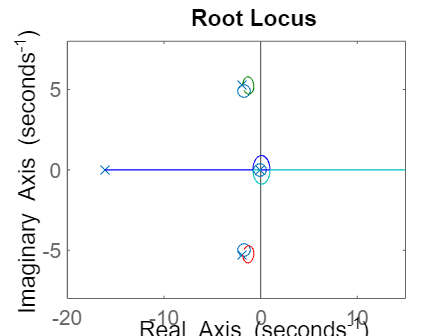

rlocus(G1)

kd1 = 0.106;
Go1 = feedback(kd1*G1,1);
Go1.OutputName= {'p'}

Go1 =
 
  From input "aileron" to output "p":
     -16.63 s^3 - 56.71 s^2 - 456 s + 13.14
  ---------------------------------------------
  s^4 + 3.164 s^3 + 34.19 s^2 + 49.08 s + 20.12
 
Continuous-time transfer function.



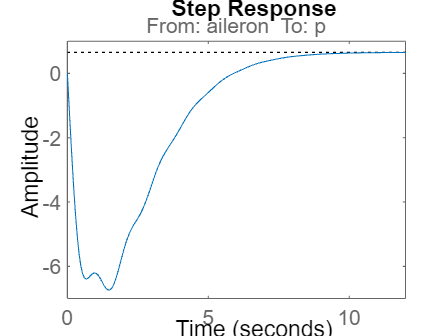

step(Go1)

stepinfo(Go1)

ans = struct with fields:
         RiseTime: 2.7315
    TransientTime: 7.8207
     SettlingTime: 10.5372
      SettlingMin: 0.5886
      SettlingMax: 0.6499
        Overshoot: 0
       Undershoot: 1.0317e+03
             Peak: 6.7379
         PeakTime: 1.4884


De la misma forma, se establece la función de transferencia para el yaw rate a partir de la entrada del rudder, que permitirá determinar la ganancia derivativa del controlador.


$$G_2 =\;\frac{r}{\mathrm{rudder}}$$


G2 = TransferFunctions(3,2)

G2 =
 
  From input "rudder" to output "r":
     -82.27 s^3 - 1393 s^2 - 1237 s - 2365
  -------------------------------------------
  s^4 + 19.8 s^3 + 90.9 s^2 + 505.1 s + 6.979
 
Continuous-time transfer function.



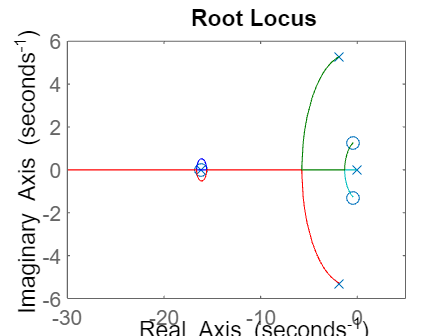

rlocus(-G2)

kd2 = -0.183;
Go2 = feedback(kd2*G2,1);
Go2.OutputName= {'r'}

Go2 =
 
  From input "rudder" to output "r":
      15.06 s^3 + 255 s^2 + 226.3 s + 432.7
  ---------------------------------------------
  s^4 + 34.85 s^3 + 345.9 s^2 + 731.4 s + 439.7
 
Continuous-time transfer function.



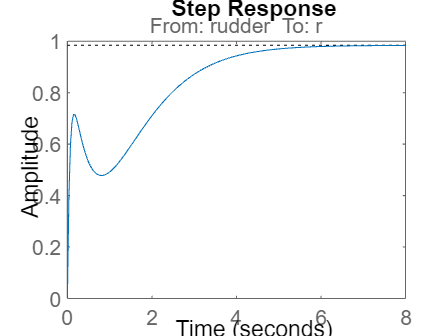

step(Go2)

stepinfo(Go2)

ans = struct with fields:
         RiseTime: 3.1306
    TransientTime: 4.6916
     SettlingTime: 4.6916
      SettlingMin: 0.8887
      SettlingMax: 0.9839
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9839
         PeakTime: 8.7119


## Retroalimentación SAS

Para realizar la retroalimentación se emplean las constantes determinadas y el sistema lateral/direccional.

TransferFunctions(2,1) = kd1*TransferFunctions(2,1);

kd =     0.1060         0
         0   -0.1830


TransferFunctions(3,2) = kd2*TransferFunctions(3,2);
SASLatMod = ss(TransferFunctions)

SASLatMod =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1         0        0        0  -0.4362        0        0        0        0        0        0        0        0
   x2      0.25        0        0   -7.892        0        0        0        0        0        0        0        0
   x3         0        8        0   -11.36        0        0        0        0        0        0        0        0
   x4         0        0        8    -19.8        0        0        0        0        0        0        0        0
   x5         0        0        0        0        0        0        0  -0.4362        0        0        0        0
   x6         0        0        0        0     0.25        0        0   -7.892        0        0        0        0
   x7         0        0        0        0        0        8        0   -11.36        0        0        0        0
   x8         0        0        0        0        0        

feedin = [1 2]

feedin =      1     2


feedout = [2 3]

feedout =      2     3


CASLatMod = feedback(SASLatMod,eye(2),feedin,feedout)

CASLatMod =
 
  A = 
             x1       x2       x3       x4       x5       x6       x7       x8       x9      x10      x11      x12
   x1         0        0        0  -0.4362        0        0        0    28.22        0        0        0    52.33
   x2      0.25        0        0   -7.892        0        0        0    6.709        0        0        0   -81.83
   x3         0        8        0   -11.36        0        0        0    4.873        0        0        0   -43.53
   x4         0        0        8    -19.8        0        0        0        0        0        0        0   -1.251
   x5         0        0        0        0        0        0        0   -1.257        0        0        0   -15.92
   x6         0        0        0        0     0.25        0        0  -0.7668        0        0        0    135.3
   x7         0        0        0        0        0        8        0   -4.274        0        0        0    77.81
   x8         0        0        0        0        0        

## Funciones de transferencia

Se comienza por encontrar las funciones de transferencia del sistema a partir del modelo lateral/direccional suministrado con la retroalimentación SAS.

CASTransferFunctions = tf(CASLatMod);

## CAS Controllers

Se comienza por establecer la función de transferencia para el roll a partir de la entrada del aileron, que permitirá determinar la ganancia proporcional del controlador.


$$G_{11} =\;\frac{\mathrm{phi}}{\mathrm{aileron}}$$


G11 = CASTransferFunctions(4,1)

G11 =
 
  From input "aileron" to output "phi":
                                                                                                                  
  -156.3 s^10 - 8961 s^9 - 2.016e05 s^8 - 2.376e06 s^7 - 1.793e07 s^6 - 1.027e08 s^5 - 4.22e08 s^4 - 1.434e09 s^3 
                                                                                                                  
                                                                         - 3.512e09 s^2 - 6.099e09 s - 8.382e07   
                                                                                                                  
  ----------------------------------------------------------------------------------------------------------------
                                                                                                                
   s^12 + 57.81 s^11 + 1392 s^10 + 2.205e04 s^9 + 3.139e05 s^8 + 3.441e06 s^7 + 2.153e07 s^6 + 6.341e07 s^5     
                                    

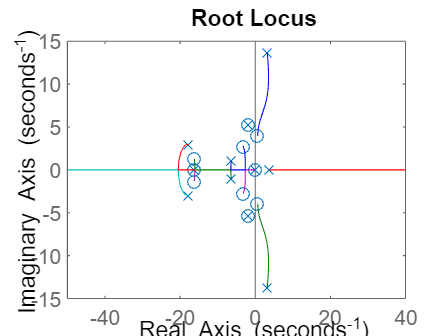

rlocus(G11)

kp1 = -0.12;
Go11 = feedback(kp1*G11,1);
Go11.OutputName= {'phi'}

Go11 =
 
  From input "aileron" to output "phi":
                                                                                                                 
  18.75 s^10 + 1075 s^9 + 2.419e04 s^8 + 2.851e05 s^7 + 2.152e06 s^6 + 1.232e07 s^5 + 5.064e07 s^4 + 1.72e08 s^3 
                                                                                                                 
                                                                         + 4.215e08 s^2 + 7.319e08 s + 1.006e07  
                                                                                                                 
  ---------------------------------------------------------------------------------------------------------------
                                                                                                                
   s^12 + 57.81 s^11 + 1410 s^10 + 2.313e04 s^9 + 3.381e05 s^8 + 3.726e06 s^7 + 2.368e07 s^6 + 7.573e07 s^5     
                                         

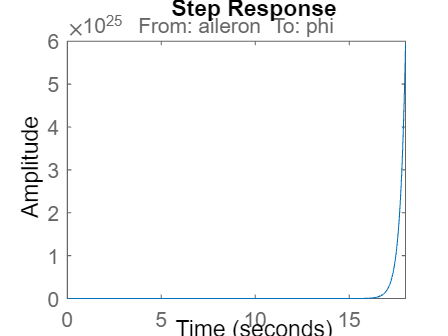

step(Go11)

stepinfo(Go11)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


De la misma forma, se establece la función de transferencia para el yaw a partir de la entrada del rudder, que permitirá determinar la ganancia proporcional del controlador.


$$G_{22} =\;\frac{\mathrm{psi}\;}{\mathrm{rudder}}$$


G22 = CASTransferFunctions(5,2)

G22 =
 
  From input "rudder" to output "psi":
                                                                                                               
  -82.39 s^11 - 3229 s^10 - 4.342e04 s^9 - 2.445e05 s^8 - 3.244e05 s^7 + 5.482e06 s^6 + 6.248e06 s^5           
                                                                                                               
                                           - 1.587e08 s^4 - 1.616e09 s^3 - 5.091e09 s^2 + 5.366e07 s + 1.716e06
                                                                                                               
  -------------------------------------------------------------------------------------------------------------
                                                                                                               
  s^13 + 57.81 s^12 + 1392 s^11 + 2.205e04 s^10 + 3.139e05 s^9 + 3.441e06 s^8 + 2.153e07 s^7 + 6.341e07 s^6    
                                                         

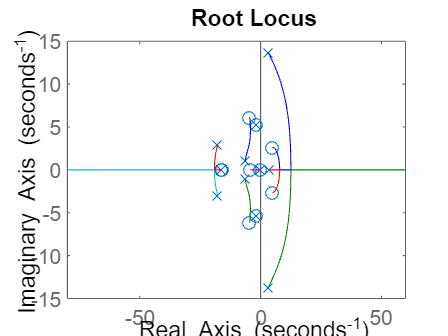

rlocus(G22)

kp2 = 0.15;
Go22 = feedback(kp2*G22,1);
Go22.OutputName= {'psi'}

Go22 =
 
  From input "rudder" to output "psi":
                                                                                                                 
  -12.36 s^11 - 484.3 s^10 - 6512 s^9 - 3.668e04 s^8 - 4.866e04 s^7 + 8.223e05 s^6 + 9.373e05 s^5 - 2.381e07 s^4 
                                                                                                                 
                                                          - 2.423e08 s^3 - 7.636e08 s^2 + 8.049e06 s + 2.574e05  
                                                                                                                 
  ---------------------------------------------------------------------------------------------------------------
                                                                                                                
   s^13 + 57.81 s^12 + 1379 s^11 + 2.157e04 s^10 + 3.074e05 s^9 + 3.405e06 s^8 + 2.148e07 s^7 + 6.423e07 s^6    
                                          

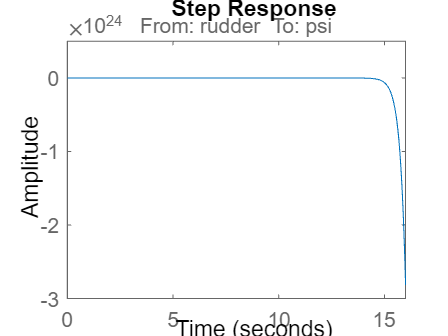

step(Go22)

stepinfo(Go22)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: NaN
       Undershoot: NaN
             Peak: Inf
         PeakTime: Inf


Como se observa las respuestas no son las esperadas y se debe a la inestabilidad que se produce al realizar la realimentación SAS y todos los problemas que ya se mencionaron en el informe presentado.

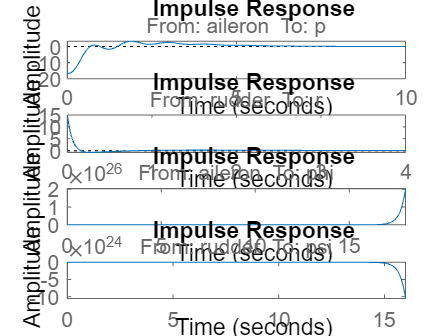

figure();
subplot(4,1,1)
impulse(Go1);
subplot(4,1,2)
impulse(Go2);
subplot(4,1,3)
impulse(Go11);
subplot(4,1,4)
impulse(Go22);